# Question 5

## Part 1

**Step 1:** Generate the original signal x[n]

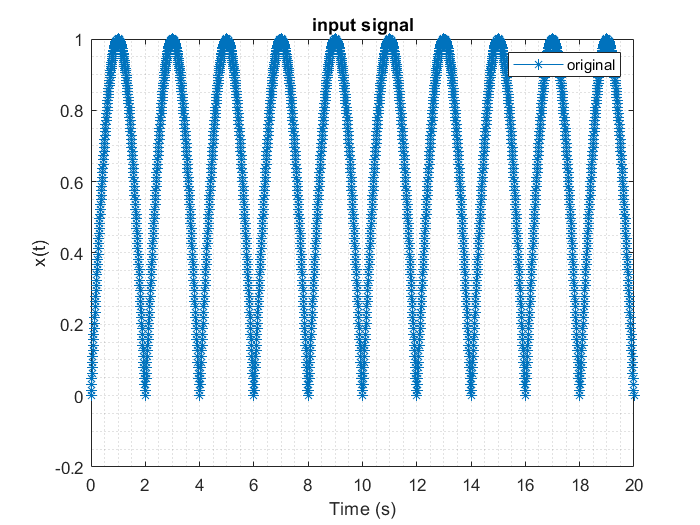

t_original = 0:0.01:4;
x_original(1,1:200) = sin(pi*0.5*t_original(1:200));
x_original(1,201:401) = -sin(pi*0.5*t_original(201:end));

t_w5 = 0:0.01:20; % time of 5 period
x_original_w5 = [x_original x_original(2:end) x_original(2:end) x_original(2:end) x_original(2:end)];

figure;
plot(t_w5,x_original_w5,'-*'); grid minor;
xlabel('Time (s)'); ylabel('x(t)'); title('Input signal x(t) over 5 period');
legend('original');

**Step 2: **Generate fourier series a_k by [7 9 11 21 51] elements and calculate x(t) signals respectively

num = [7 9 11 21 51];
k_range = (num - 1)./2;
x = zeros(length(k_range),length(t_original));
% first row of x will be in 7 range
% second row of x will be in 9 range and so on and on...

coeff1 = zeros(1,num(1));
coeff2 = zeros(1,num(2));
coeff3 = zeros(1,num(3));
coeff4 = zeros(1,num(4));
coeff5 = zeros(1,num(5));


t = 0;
for m = 1:length(k_range)
    for i = 1:length(t_original)

        for k = -k_range(m):1:k_range(m)
            if k==1 || k==-1
                ak = 0;
            else
                ak = (-0.5/pi)*( (cos(pi*(k+1))-1)/(k+1) + (cos(pi*(1-k))-1)/(1-k) );
            end
            x(m,i) = real(x(m,i) + ak*exp(1j*k*pi*0.5*t));
            if m==1
                coeff1(k+1+k_range(m)) = ak; 
            elseif m==2
                coeff2(k+1+k_range(m)) = ak;
            elseif m==3
                coeff3(k+1+k_range(m)) = ak;
            elseif m==4
                coeff4(k+1+k_range(m)) = ak;
            else 
                coeff5(k+1+k_range(m)) = ak;
            end
                
        end

        t = t + 0.01;

    end
    t = 0;
end

**Step 3: **Gather the different coefficient in one matrix and plot them.

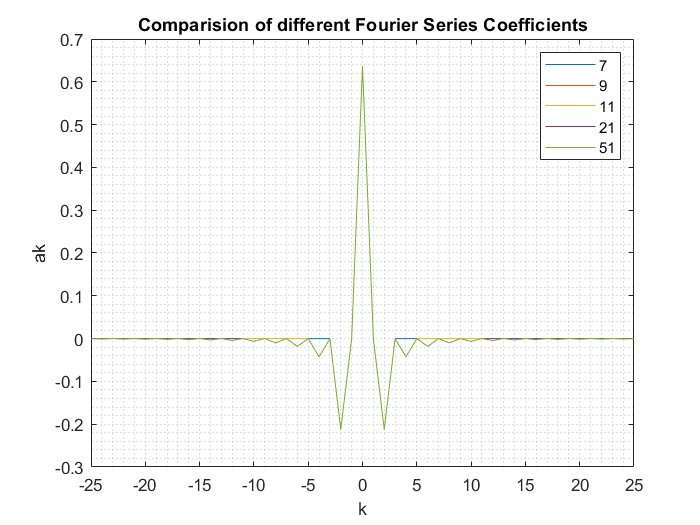

coeffs = [zeros(1,22),coeff1,zeros(1,22);
          zeros(1,21),coeff2,zeros(1,21);
          zeros(1,20),coeff3,zeros(1,20);
          zeros(1,15),coeff4,zeros(1,15);
                    coeff5];

k_ak = -25:1:25;
figure;
plot(k_ak,coeffs(1,:));
hold on;
plot(k_ak,coeffs(2,:));
plot(k_ak,coeffs(3,:));
plot(k_ak,coeffs(4,:));
plot(k_ak,coeffs(end,:)); grid minor;
xlabel('k'); ylabel('ak'); title('Comparison of different Fourier Series Coefficients');
legend('7','9','11','21','51');

**Step 4: **Compare the plots of input signals which are calculated from different fourier series ranges. (in 5 period scale)

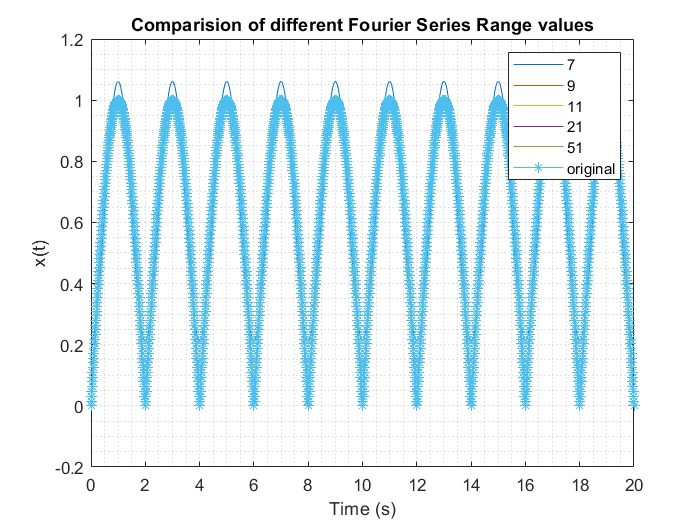

x_w5 = zeros(5,length(t_w5));
for u=1:5
    x_w5(u,:) = [x(u,:) x(u,2:end) x(u,2:end) x(u,2:end) x(u,2:end)];
end

figure;
plot(t_w5,x_w5(1,:));
hold on;
plot(t_w5,x_w5(2,:));
plot(t_w5,x_w5(3,:));
plot(t_w5,x_w5(4,:));
plot(t_w5,x_w5(end,:));
plot(t_w5,x_original_w5,'-*'); grid minor;
xlabel('Time (s)'); ylabel('x(t)'); title('Comparison of different Fourier Series Range values');
legend('7','9','11','21','51','original');

**Comment: **From the last plot of the question, it can be seen that how far we expand the range of fourier series coefficients (ideally infinity), it converges to the original input signal.

## Part 2

**Step 1:** Adding delay to the coefficients.

Since the x(t) = Σ(a_k).exp(j.k.w.t) and x(t - t_0) = Σ(a_k).exp(j.k.w.(t - t_0))

which can be also written as x(t - t_0)= Σ(a_k*exp(j.k.w.(t_0))).exp(j.k.w.t).

So our new coefficient b_k = a_k*exp(j.k.w.(t_0))

The delay that is indicated in the question t_0 = 1.

t_0 = 1;

num_D = [11,51,91];
k_range_D = (num_D - 1)./2;
x_D = zeros(length(k_range_D),length(t_original));
coeff1_D = zeros(1,num(1));
coeff2_D = zeros(1,num(2));
coeff3_D = zeros(1,num(3));

t = 0;
for m = 1:length(k_range_D)
    for i = 1:length(t_original)

        for k = -k_range_D(m):1:k_range_D(m)
            
            if k==1 || k==-1
                bk = 0;
            else
                bk = (-0.5/pi)*( (cos(pi*(k+1))-1)/(k+1) + (cos(pi*(1-k))-1)/(1-k) );
            end
            
            delay = exp(1j*k*pi*0.5*(t_0));
            bk = bk*delay;
            
            x_D(m,i) = real(x_D(m,i) + bk*exp(1j*k*pi*0.5*t));
            
            if m==1
                coeff1_D(k+1+k_range_D(m)) = bk; 
            elseif m==2
                coeff2_D(k+1+k_range_D(m)) = bk;
            else 
                coeff3_D(k+1+k_range_D(m)) = bk;
            end
                
        end

        t = t + 0.01;

    end
    t = 0;
end

**Step 2: **Plot the delayed coefficients

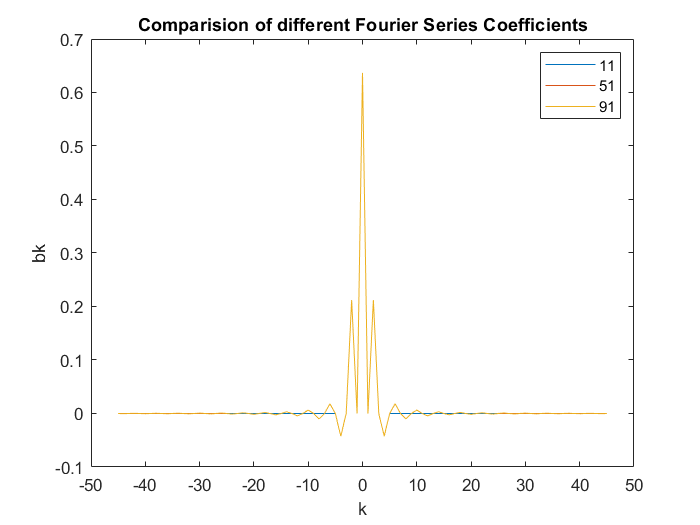

coeffs_D = [zeros(1,40),coeff1_D,zeros(1,40);
            zeros(1,20),coeff2_D,zeros(1,20);
                        coeff3_D];

coeffs_D = real(coeffs_D);
k_bk = -45:1:45;
figure;
plot(k_bk,coeffs_D(1,:));
hold on;
plot(k_bk,coeffs_D(2,:));
plot(k_bk,coeffs_D(3,:));
xlabel('k'); ylabel('bk'); title('Comparison of different Fourier Series Coefficients');
legend('11','51','91');

**Step 3: **Plot the delayed and original waveforms

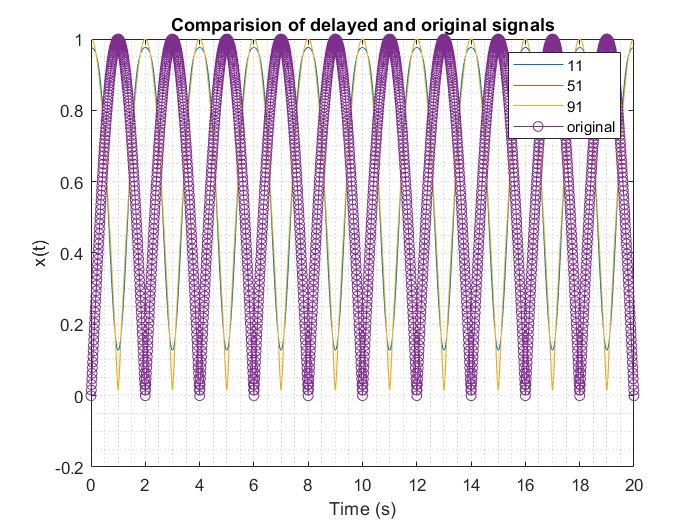

x_D_w5 = zeros(5,length(t_w5));
for u=1:3
    x_D_w5(u,:) = [x_D(u,:) x_D(u,2:end) x_D(u,2:end) x_D(u,2:end) x_D(u,2:end)];
end

figure;
plot(t_w5,x_D_w5(1,:));
hold on;
plot(t_w5,x_D_w5(2,:));
plot(t_w5,x_D_w5(3,:));
plot(t_w5,x_original_w5,'-o'); grid minor;
xlabel('Time (s)'); ylabel('x(t)'); title('Comparison of delayed and original signals');
legend('11','51','91','original');